# Parzen窗估计的解法(高斯窗)

## 一、公式推导

- 已知Parzen窗的概率密度估计公式：

$\hat{p}_N(X)=\frac{k_N/N}{V_N}=\frac{1}{N}\sum\limits^N_{i=1}\frac{\varphi(\frac{X-X_i}{h_N})}{V_N}$ ①

- 高斯窗定义为：

$\varphi(u)=\frac{1}{\sqrt{2\pi}}exp\{-\frac{1}{2}u^2\}$②

则有：

$\varphi(\frac{X-X_i}{h_N})=\frac{1}{\sqrt{2\pi}}exp[-\frac{1}{2}(\frac{X-X_i}{h_N})^2]$③

- 本题已知$h_N=\frac{h_1}{\sqrt{N}}$，代入③式得：

$\varphi(\frac{X-X_i}{h_N})=\frac{1}{\sqrt{2\pi}}exp[-\frac{1}{2}(\frac{X-X_i}{h_{1}/ \sqrt{N}})^2]$④

- 本题中$X$均为实数，$d=1$，则$V_N =h_N =\frac{h_1 }{\sqrt{N}}$，将其代入①式得：

$\hat{p}_N(X)=\frac{1}{h_1\sqrt{N}}\sum\limits^N_{i=1}\varphi(\frac{X-X_i}{h_N})$⑤

- 将③式代入⑤式中得：

$\hat{p}_N(X)=\frac{1}{h_1\sqrt{N}}\frac{1}{\sqrt{2\pi}}\sum\limits^N_{i=1}exp[-\frac{1}{2}(\frac{X-X_i}{h_1/\sqrt{N}})^2]$⑥

- 本题正是根据⑥式进行计算。

## 二、调用脚本

### 1. 验证x随机性

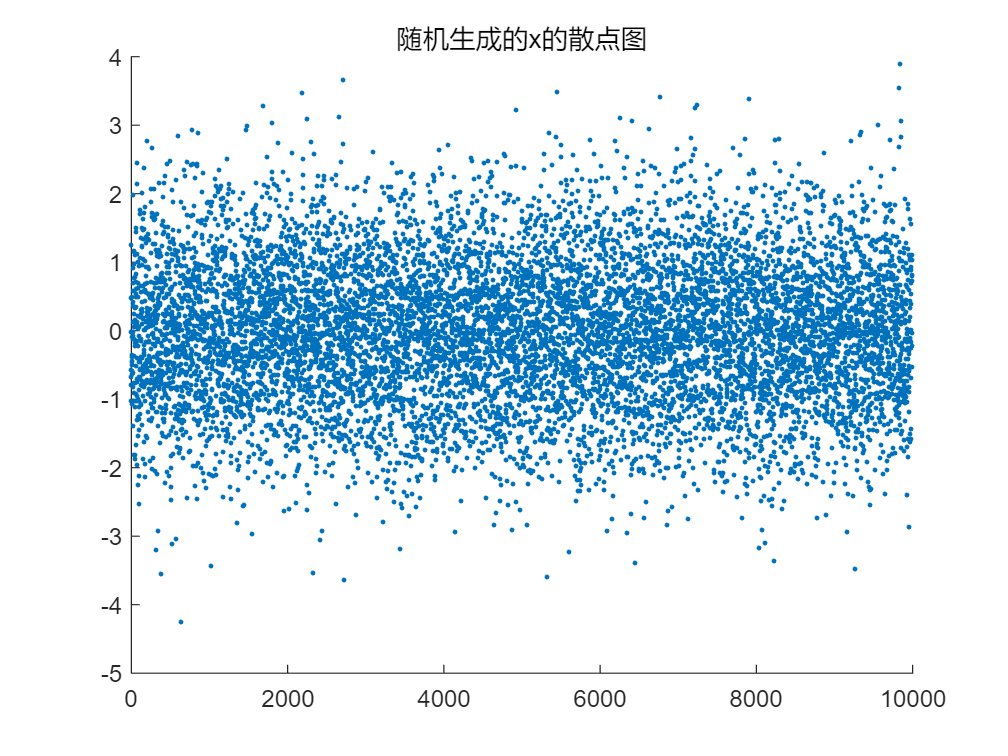

x = randn(1, 10000);
x(x <- 6) = -6;
x(x > 6) = 6;
% 生成正态分布的伪随机数
scatter(1:1:numel(x), x, '.');
title("随机生成的x的散点图");

- 以$x$的序列为横轴，$x_i$为纵轴，可以观察到这些点是无序的，所以parzen_GaussWindow函数从$x$中取前$N$个值同样可以认为是从正态分布中随机取样。

### 2. 计算、绘图

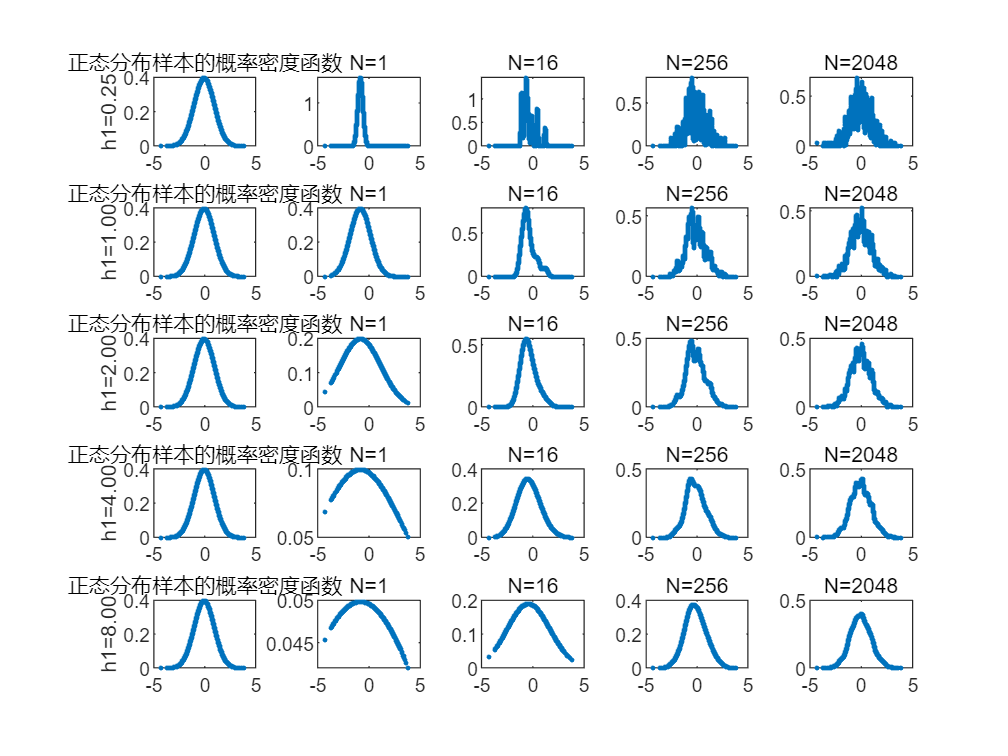

px = normpdf(x,0,1); % 按照μ=0，σ=1的正态分布计算每个x对应的概率密度函数值
h1 = [0.25, 1, 2, 4, 8]; % 调节参数
N = [1, 16, 256, 2048]; % 样本数

for i_h1 = 1:length(h1) % 遍历h1
    h1_offset = (i_h1 - 1) * (numel(N) + 1) + 1; % 绘图位置的偏移量
    subplot(numel(h1), numel(N) + 1, h1_offset);
    plot(x, px, '.');
    ylabel(sprintf('%s%4.2f', 'h1=', h1(i_h1)));
    title('正态分布样本的概率密度函数');

    for i_N = 1:length(N)
        pNx = parzen_GaussWindow(N(i_N), h1(i_h1), x);
        subplot(numel(h1), numel(N) + 1, h1_offset + i_N);
        plot(x, pNx, '.');
        title(sprintf('%s%d', 'N=', N(i_N)));
    end
end

## 三、主函数

由于MATLAB的实施编辑器要求必须先写

function parzen = parzen_GaussWindow(N, h1, x)
    %% 高斯窗Parzen窗
    % N : 取样个数
    % h1: 用以计算窗函数的宽度
    % x : 数据集
    hN = h1 / sqrt(N); % 计算hN
    parzen = zeros(1, numel(x));

    for u = 1:numel(x) % 遍历每个样本点x(u)，(公式中的X)
        for i = 1:N % 遍历每个取样点x(i)，(公式中的Xi)，通过这个循环完成式⑥中的累加部分
            parzen(u) = parzen(u) + exp((((x(u) - x(i)) / hN)) .^ 2 / -2);
        end
        parzen(u) = parzen(u) / sqrt(2 * pi) / h1 / sqrt(N); % 累加完成之后，再乘以式⑥中Σ前面的部分才得到概率密度
    end
end

- 可见，该函数直接完成了在指定$N$和$h_1$的情况下$\hat{p}_N(X)$的计算。